Here We may solver N-ODE as

           
$$\dot{x} =-x+x^{2\;} \;\;\;\;,x\left(0\right)=0\ldotp 5\;\;,D=\left\lbrack 0\;\;5\right\rbrack$$


$f=-x+x^2 \;$ is locally Lipschitz in x on $D$ 

What is the solution? We may use symbolic math as

clear variables
syms x(t) t
D=[0 5];
% f = diff(x)+x-x^2;
% cond = x(0) == 1;
cond = x(0) == 0.5;
ode = diff(x(t),t)+x(t) -x(t)^(2) ==0;
xSol(t) = dsolve(ode, cond)

$$xSol(t) = \frac{1}{{\mathrm{e}}^{t}+1}$$

OK. Now if you are not convinced this result (you should be), Since it is a locally Lipschitz, the solution is uique, and 

% initial condition
xSol(0)

$$ans = \frac{1}{2}$$

% Substitute to the original ODE
simplify(diff(xSol(t)) +xSol(t) - xSol(t)^2)

$$ans = 0$$

- Ex_1 

Given 

                 
$$\dot{x} =-x^{3\;} \;\;,x\left(0\right)=-1$$


1) Find the analytic solution 

2) Check the solution satify the ODE

3) Plot for $t\in \;\left\lbrack 0\;\;\;\;5\right\rbrack$

- complex e-values

Problem : Given a complex eigenvalues $a\pm \textrm{jb}$ of $A$, find a similar transform $P$ such that 

               
$$\;A={\textrm{PVP}}^{-1} ,V=\left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack \;$$


Hence given original system as 

                 
$$\dot{x} =\textrm{Ax}\;$$


Transform to a new state $y$ as $\;y=P^{-1} x\;$ so that new state  LDE is 

              
$$\dot{\;y} ={\textrm{PVP}}^{-1\;} y\;\;=\left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack y\;$$


So that in $\left(r,\theta \;\right)\;$ coordiante

               
$$\frac{\textrm{dr}}{\textrm{dt}}=\textrm{ar}\;,\frac{d\theta }{\textrm{dt}}=b\;$$


 which is the solution as 

             
$$r\left(t\right)\;=r_{0\;} e^{\textrm{at}} \;\;,\theta \left(t\right)=\theta_{0\;} +\textrm{bt}$$
            

Solution_1:

    Let 

               
$$A\;=\left\lbrack \begin{array}{cc}
x_{11}  & x_{12} \\
x_{21}  & x_{22} 
\end{array}\right\rbrack ,P=\left\lbrack \begin{array}{cc}
p_{11}  & p_{12} \\
p_{21}  & p_{22} 
\end{array}\right\rbrack$$


 Then 

                       
$$\textrm{AP}=\textrm{VP}$$


So that 

                   
$$\left\lbrack \begin{array}{cc}
x_{11}  & x_{12} \\
x_{21}  & x_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
p_{11}  & p_{12} \\
p_{21}  & p_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
p_{11}  & p_{12} \\
p_{21}  & p_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack \;$$


You may expand it as

                     
$$x_{11} p_{11} +x_{12} p_{21} =p_{11} a-p_{12} b$$


                     
$$x_{11} p_{12} +x_{12} p_{22} =p_{11} b+p_{12} a$$


                     
$$x_{21} p_{11} +x_{22} p_{21} =p_{21} a-p_{22} b$$


                    
$$x_{21} p_{12} +x_{22} p_{22} =p_{21} b\;+p_{22} a$$


Here the solution to the linear equations, 

  1) $P=0$ which is trivial and is not the desired one

   2) Since this is homogeneous linear equation, if 

 $\textrm{AP}=\textrm{VP}=\left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack P\;$. Define the corresponding e-vector $x_1 =\textrm{Re}\left(x_1 \right)+\textrm{jIm}\left(x_1 \right)$,

here , $\textrm{Re}\left(x_1 \right)\in R^2 ,\textrm{Im}\left(x_1 \right)\in R^2$. Then from ${\textrm{Ax}}_{1\;} =\lambda {\;}_{1\;} x_{1\;} =\left(a+\textrm{jb}\right)\;$

             $A\;x_{1\;} =A\;\left\lbrack \textrm{Re}\left(x_1 \right)+\textrm{jIm}\left(x_1 \right)\right\rbrack =\left(a+\textrm{jb}\right)\left\lbrack \textrm{Re}\left(x_1 \right)+\textrm{jIm}\left(x_1 \right)\right\rbrack$,

so that

                               
$$\begin{array}{l}
\textrm{ARe}\left(x_1 \right)=\textrm{aRe}\left(x_1 \right)-\textrm{bIm}\left(x_1 \right)\\
\textrm{AIm}\left(x_1 \right)=\textrm{bRe}\left(x_1 \right)+\textrm{aIm}\left(x_1 \right)
\end{array}$$


The RH is  

                                
$$\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\;\textrm{Im}\left(x_1 \right)\right\rbrack \left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack$$


The LH is 

             
$$\left\lbrack A\;\textrm{Re}\left(x_1 \right)\;\textrm{AIm}\left(x_1 \right)\right\rbrack =A\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\textrm{Im}\left(x_1 \right)\right\rbrack$$


Combiming LH with RH is 

           
$$A\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\textrm{Im}\left(x_1 \right)\right\rbrack =\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\;\textrm{Im}\left(x_1 \right)\right\rbrack \left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack \;$$


so that 

            
$$A\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\textrm{Im}\left(x_1 \right)\right\rbrack =\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\;\textrm{Im}\left(x_1 \right)\right\rbrack \left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack {\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\textrm{Im}\left(x_1 \right)\right\rbrack }^{-1} \;$$


i.e., 

              
$$P=\left\lbrack \textrm{Re}\left(x_1 \right)\;\;\textrm{Im}\left(x_{1\;} \right)\right\rbrack$$


   Ex. 2(1.11)

                
$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & -0\ldotp 3
\end{array}\right\rbrack$$


clear variables;
A = [0 1; -1  -0.3];
[Vec,Val]=eig(A)% confirm eigen value and eigen vector 

The eigvalue and eigenvector are

   
$$\lambda_1 =-0\ldotp 15+0\ldotp 9887\;i,\;\;\;\;\;\;\;\;\;v_1 =\left\lbrack \begin{array}{c}
0\ldotp 7071\\
-0\ldotp 1061+0\ldotp 6991i
\end{array}\right\rbrack$$


  
$$\lambda_2 =-0\ldotp 15\;-0\ldotp 98871\;i,\;\;\;\;v_2 =\left\lbrack \begin{array}{c}
0\ldotp 7071\\
-0\ldotp 1061-0\ldotp 6991i
\end{array}\right\rbrack$$


We may verify the results using $\textrm{Ax}=\lambda \;x$

A*Vec(:,1)
Vec(:,1)*Val(1,1)

A*Vec(:,2)
Vec(:,2)*Val(2,2)

The values are equivalent to each other, so that verifyed. If eigenvector is real, then it can be depicted in $\left(x,y\right)\;,\;x,y\;\in R$ plane, but if it is not a  real vector, it can NOT be draw in the $\left(x,y\right)\ldotp$ How can it be drawn in some plane? The idea is for any $x\in C^2 ,\;C:\textrm{complex}\;\textrm{space}$

         
$$x={\textrm{re}}^{j\theta } ,\;\;r\;\in R\;,\theta \in R$$


Hence we may a trajectory in the $\left(r,\theta \;\right)$ plane 

Now 


$$\lambda_1 =-0\ldotp 15+0\ldotp 9887\;i,\;\;\;\;\;\;\;\;\;v_1 =\left\lbrack \begin{array}{c}
0\ldotp 7071\\
-0\ldotp 1061+0\ldotp 6991i
\end{array}\right\rbrack$$


% define P matrix
P =[0.7071  0;-0.1061  0.6991]
inv(P)*A*P

Here

       
$$V=P^{-1\;} \textrm{AV}=\left\lbrack \begin{array}{cc}
a & b\\
-b & a
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-0\ldotp 15 & 0\ldotp 9887\\
-0\ldotp 9887 & -0\ldotp 15
\end{array}\right\rbrack$$


so that 

         
$$r\left(t\right)=r_0 e^{-0\ldotp 15t} \;\;,\theta =\theta_0 +0\ldotp 9887t$$


which is the magnitude decreasing spiral trajectories. 

- Systems of Equations -LODE

Here system equation as

              
$$\begin{array}{l}
\dot{\;x} =y\\
\dot{y\;} =-x\;\;\;\;\;x\left(0\right)=1\;,y\left(0\right)=0\;\;,t\in \left\lbrack 0,10\pi \;\right\rbrack 
\end{array}$$
    

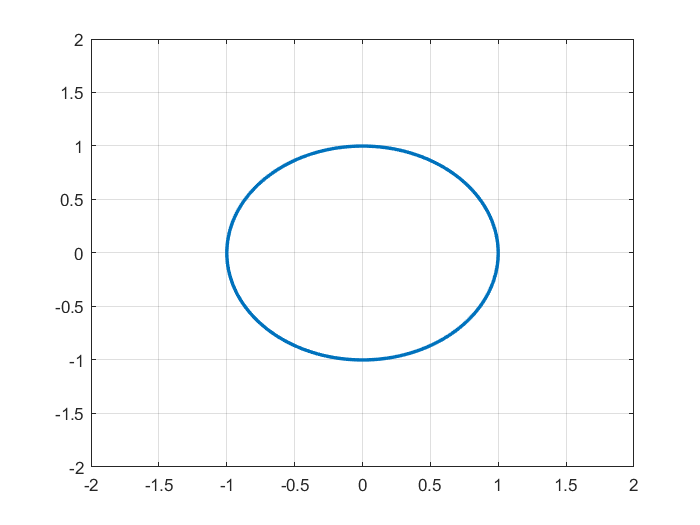

clear variables;
LW ='linewidth';
L = chebop(0, 10*pi);
L.op =@(t,x,y)[diff(x) - y; diff(y) + x];
L.lbc =@(x,y) [x-1; y];
rhs =[0;0];
U=L\ rhs;
% plot(U)
plot(U(1), U(2),LW,2);grid on
axis([-2 2 -2 2]); 

Here $x\left(t\right)$ is a circle with $\left(x_{0\;} ,y_{0\;} \right)\ldotp$

**HW.1** Draw the trajectories with different initial conditions in the same figure as 

1)  $\left\lbrack x\left(0\right),y\left(0\right)\right\rbrack \;=\left\lbrack 0,1\right\rbrack \;,\left\lbrack 0,-1\right\rbrack ,\left\lbrack -1,0\right\rbrack$

2) $\left\lbrack x\left(0\right),y\left(0\right)\right\rbrack \;=\left\lbrack 0\ldotp 5\;,0\right\rbrack \;,\left\lbrack 0,\;2\right\rbrack ,\left\lbrack 2,0\right\rbrack$   -End-

Good. How about trajectory the above example? Now if the radis is decreasing (called stable focus), or increasing(called unstable focus) at the origin. 

Consider $\dot{x} =\textrm{Ax},x\left(0\right)=1,y\left(0\right)=0$, 

                            
$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & -0\ldotp 3
\end{array}\right\rbrack$$


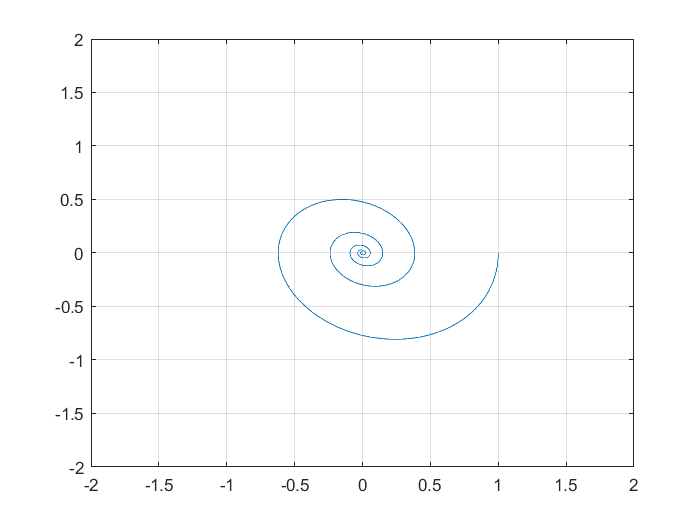

clear variables;
LW='linewidth'
L = chebop(0, 10*pi);
L.op =@(t,x,y)[diff(x) - y; diff(y) + x + 0.3*y];
L.lbc =@(x,y) [x-1; y];
rhs =[0;0];
U=L\ rhs;
% plot(U)
plot(U(1), U(2));grid on
axis([-2 2 -2 2]); 

Hence $x\left(t\right)\;$is a spiral motion convergent to zero,** stable focus**.

           
$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & 0\ldotp 3
\end{array}\right\rbrack$$


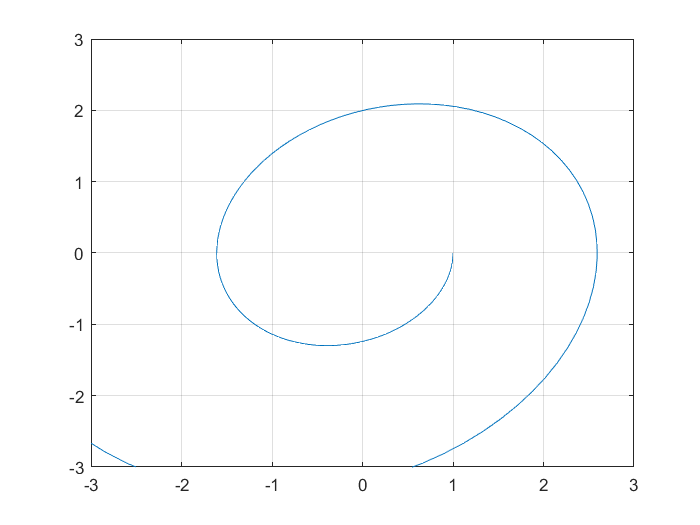

clear variables;
L = chebop(0, 10*pi);
L.op =@(t,x,y)[diff(x) - y; diff(y) + x - 0.3*y];
L.lbc =@(x,y) [x-1; y];
rhs =[0;0];
U=L\ rhs;
% plot(U)
plot(U(1), U(2));grid on
axis([-3 3 -3 3]); 

Hence $x\left(t\right)\;$is a spiral motion convergent to zero,** unstable focus**.

- Kim's Eigen-Value/ eigen-vector

1) eigen-value / eigen-vector  

$\;$What is the  eigenvalue / eigenvector? By definition given a square matrix $A\in R^{2\textrm{x2}}$, $\exists \;x_e \in R^2 \;\textrm{and}\;\lambda_e \;$ s.t. 

                       
$${\textrm{Ax}}_e =\lambda x_e$$


In L -ODE, what is implication? Consider 

                                      
$$\dot{x\;} =\textrm{Ax}\;$$


 If the initial condtion $x\left(0\right)=x_e$, then

       
$$\dot{x\;} =\textrm{Ax}={\textrm{Ax}}_e \;\;\;-\to \frac{1}{\textrm{dt}\;}\left(x\left(t+\textrm{dt}\right)-x\left(t\right)\right)=\textrm{Ax}\left(t\right)$$


Let $t=0$, then

      
$$\frac{1}{\textrm{dt}\;}\left(x\left(t+\textrm{dt}\right)-x\left(t\right)\right)=\textrm{Ax}\left(t\right)=\frac{1}{\textrm{dt}}\left(x\left(\textrm{dt}\right)-x\left(0\right)\right)=\textrm{Ax}\left(0\right)\;$$


Since $x\left(0\right)=x_e$, the RHS is

     
$$\frac{1}{\textrm{dt}}\left(x\left(\textrm{dt}\right)-x\left(0\right)\right)=\frac{1}{\textrm{dt}}x\left(\textrm{dt}\right)-\frac{1}{\textrm{dt}}x_e =\lambda {\;}_e x_e$$


i.e.,

     
$$x\left(\textrm{dt}\right)=\left(\lambda_e \textrm{dt}+1\right)x_e$$


means $x\left(\textrm{dt}\right)$ is in the same direction of $x_e =x\left(0\right)$ with scale $\left(\lambda_e \textrm{dt}+1\right)$

i.e, $x\left(t\right)$ is on the direction of $x_e \;\;\;\forall \;t\ge 0$ with a scaler. 

- Qualtitatuve analysis - Phase plane 

 2) 2-nd order ODE

Consider

                     
$$\left\lbrack \begin{array}{c}
\dot{x\;} \\
\dot{y\;} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f\left(x,y\right)\\
g\left(x,y\right)
\end{array}\right\rbrack$$


We may analyze the solution trajectories with different initials points without the exact solution.In the model, ${\left\lbrack f\left(x,y\right)\;,g\left(x,y\right)\right\rbrack }^T \;$ is known, which is called velocity vector, if we draw the velocity , we may draw get a clue the trajectory of the position qualitatively  in the ${\left\lbrack x,y\right\rbrack }^{T\;}$ plane. Hence  in general , Vectors are composed of their magnitude and **phase**, and phase represent the direction of vector, for simply drawing, we may normalize the magnitude of each vector, which is called in phase plane anaysis.

3) Linear ODE

 Consider LODE in two dimension case 

                        
$$\left\lbrack \begin{array}{c}
\dot{x\;} \\
\dot{y\;} 
\end{array}\right\rbrack =A\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack ,A\in R^{2\textrm{x2}}$$


Here we may find the e-values and e-vectors

  3.1) case 1 : e-values are real example

                       
$$\left\lbrack \begin{array}{c}
\dot{x\;} \\
\dot{y\;} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-1 & 3\\
0 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack ,A\in R^{2\textrm{x2}}$$


clear all;clf;
A =[1 2;1 -2]
[V,D] =eig(A)
LW ='linewidth';
x =linspace(-5,5,100);
x1 =V(1,1)*x;
y1 =V(2,1)*x;
x2 =V(1,2)*x;
y2 =V(2,2)*x;
plot([0 0],[-5 5]); hold on     
plot([-5 5],[0 0]);           
plot(x1,y1,LW,2); hold on
plot(x2,y2,LW,2)
axis([-4 4 -4 4])

hold off

Now if initial point is on the e-vector, the $x\left(t\right)$ will be convergent to $\left(0,0\right)$ since the e-values are negative. 

the sign of e-value. Now the other initial points should be  directed to zero according the relative magnitude of each e-values. 

In the text book

                            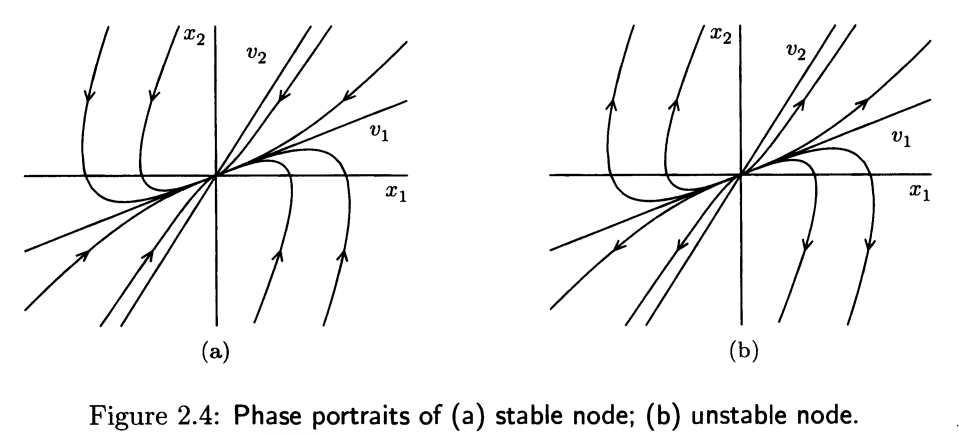

If the all e-values are real negative, the origin is said to be a stable node, or all e-values are positive, the origin is said to be a unstable node. One is positive and the other is negative, the origin is said to be **a saddle point **as

                         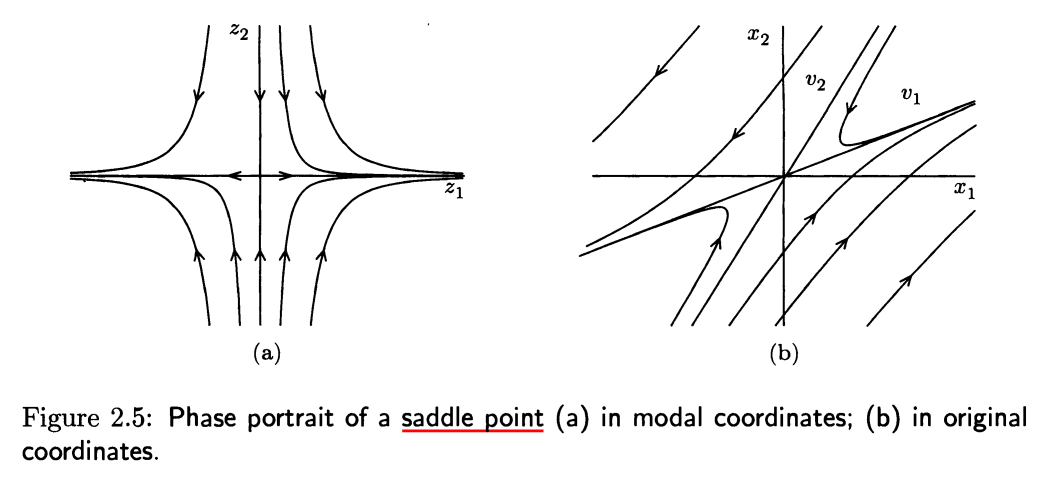 

here modal co-ordinate is the system matrix is transformed in a diagonal matrix.

-   drawing a phase plane example using "quiver" 

1) oscillation  

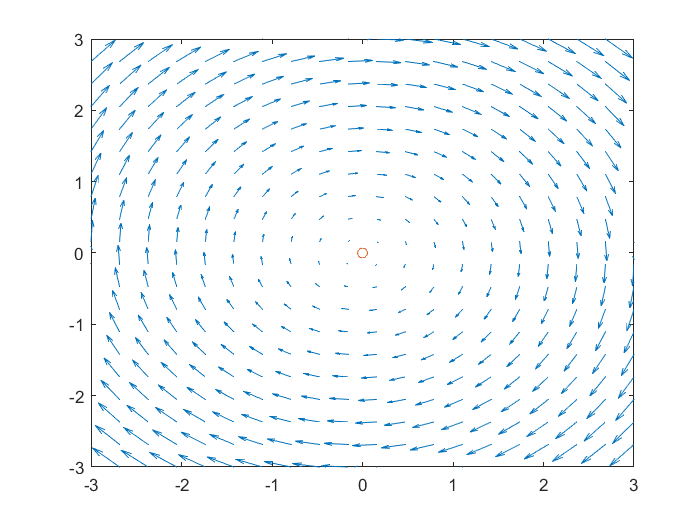

clear all;
L = chebop(@(t,x,y) [ diff(x) - y; diff(y)+x]);
quiver(L, [-3 3 -3 3])
hold on
plot(0,0,'o')
hold off

2) saddle node

clear all;
L = chebop(@(t,x,y) [ diff(x)- y; diff(y)-x]);
quiver(L, [-3 3 -3 3])
hold on
plot(0,0,'o')

3) unstable

  If the magitude of arrows are normalized, 

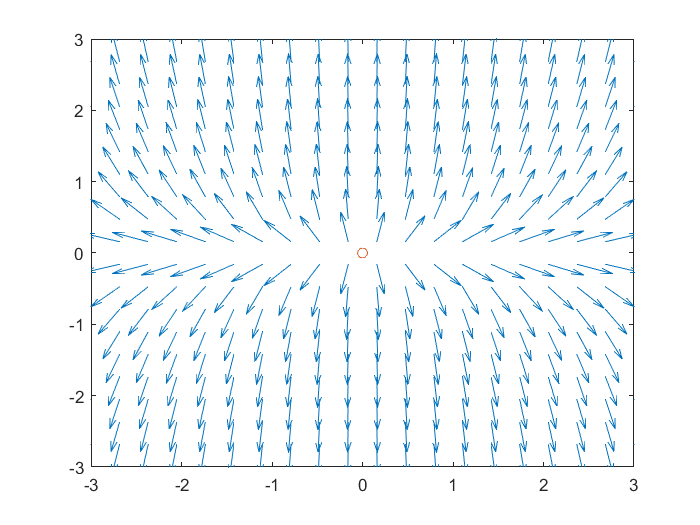

clear all;
L = chebop(@(t,x,y) [ diff(x)-x; diff(y)- 5*y]);
quiver(L, [-3 3 -3 3],'normalize',1)
hold on
plot(0,0,'o')
hold off

**HW_2**

Draw the trajectory of the solution in Ex.2.1 (pp. 35) with initial conditions as

    1) $\left\lbrack x_1 \left(0\right)\;,x_2 \left(0\right)\right\rbrack =\left\lbrack 1\;,0\right\rbrack$

    2) $\left\lbrack x_1 \left(0\right)\;,x_2 \left(0\right)\right\rbrack =\left\lbrack 0,1\right\rbrack$

    3) $\left\lbrack x_1 \left(0\right)\;,x_2 \left(0\right)\right\rbrack =\left\lbrack 1,1\right\rbrack$

**HW_3**

Consider

      
$$\begin{array}{l}
\dot{x} =2x-\textrm{xy}\\
\dot{y\;} =2x^2 -y
\end{array}$$


1) find equilibrium points

2) draw a phase plane

- Limit cycle : Van der Pol,  (Ch 2.4)

Consider

         
$$\ddot{y\;} \;-\mu \;\left(1-y^{2\;} \right)\dot{y\;} +y=0\;,t\in \left\lbrack 0,15\right\rbrack$$


With different $\mu \;$ the trajectorise  are different,

1) $\mu \;=0;\;$Oscillations 

2) $\mu =0\ldotp 125$; the circles are distored 

3) $\mu =1$; regardless of initial points the trajectories converge to only one isolated orbit.

Here different $u$ and two different initial conditions as


$$\left\lbrack y\left(0\right),\dot{y} \left(0\right)\right\rbrack =\left\lbrack 1,0\right\rbrack ,\textrm{and}\;\left\lbrack 3,0\right\rbrack \;$$


the solution trajectories are 

clear all
N = chebop(0,15);
for j = 1:3
    subplot(1,3,j)
    mu=0;  
        if j==2,   
            mu = 0.125;   
        elseif j==3,
            mu = 1;
        end 
    N.op = @(t,y) diff(y,2)-mu*(1-y^2)*diff(y)+y; 
    for a=[1 3]
        N.lbc = [a;0]; 
        y = N\0;   
        arrowplot(y,diff(y)),grid on, hold  on
    end
    plot(0,0,'.r')
    axis([-4 4 -4 4])
end

Analysis

 1) $\mu \;=0$, hence 

        
$$\ddot{y\;} \;-\mu \;\left(1-y^{2\;} \right)\dot{y\;} +y=0\;,t\in \left\lbrack 0,15\right\rbrack$$


to be 

         
$$\ddot{y\;} \;+y=0\;,t\in \left\lbrack 0,15\right\rbrack \;$$


which is a linear equation, and the trajectories are closed circles.

2) $\mu \;=0\ldotp 125$, hence 

        
$$\ddot{y\;} \;-\mu \;\left(1-y^{2\;} \right)\dot{y\;} +y=0\;,t\in \left\lbrack 0,15\right\rbrack ,y\left(0\right)=3,\dot{y} \left(0\right)=0$$


 Then the origin is an unstable focus. 

2) $\mu \;=1$, the trajectories converge a closed trajectories as time approaches to infinite, called a limit cycle. 

**HW_4**

Regarding to van der Pol equation draw phase plane for each cases as

1) Change into a state space model as

           
$$y=x_{1\;} \;,\dot{y} =x_{2\;}$$


2) In the space model, is this local Lipschitz or global Lipschitz?

3) Draw the phase plane in each case 

     3.1) $\mu =0$

     3.2) $\mu =0\ldotp 125$

     3.3) $\mu =1$

- Chaos : Lorenz equation

A deteministic system  acts as a random. It was shown that the dimension should be greater than 2, i.e, there is no chaos behavior. 

clear all;clf
N = chebop(0,30);
N.lbc =[-15;-15;20];
N.op = @(t,u,v,w) [diff(u)-10*(v-u);...
    diff(v)- u*(28-w)+v; diff(w)-u*v+(8/3)*w];
[u,v,w] = N\0;
plot3(u,v,w)
plot(u,w)
c = 6*sqrt(2);
hold on
plot([0 c -c], [0 27 27], 'o')